clear all
MouseToAvoid=[560,117,431]; % mice with noisy data to exclude
SessionNames={'UMazeCond_EyeShock', 'UMazeCondBlockedShock_EyeShock', 'UMazeCondBlockedSafe_EyeShock'};
Files=PathForExperimentsEmbReact(SessionNames{1});
Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
for mm=1:length(Files.path)
    SpecData{mm}.Shock=[];SpecData{mm}.Safe=[];
    SpecDataH{mm}.Shock=[];SpecDataH{mm}.Safe=[];
    SpecDataHLo{mm}.Shock=[];SpecDataHLo{mm}.Safe=[];
    AllSpecHPC{mm}=[];AllSpec{mm}=[];
    for ss=1:length(SessionNames)
        Files=PathForExperimentsEmbReact(SessionNames{ss});
        Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
        
        for c=1:3
            cd(Files.path{mm}{c})
            load('behavResources_SB.mat')
            dt=median(diff(Range(Behav.Vtsd,'s')));
            if not(isempty(Behav.FreezeAccEpoch))
                FreezeEpoch=Behav.FreezeAccEpoch;
            else
                FreezeEpoch=Behav.FreezeEpoch;
            end
            load('B_Low_Spectrum.mat')
            fLow=Spectro{3};
            Sptsd=tsd(Spectro{2}*1e4,Spectro{1});
            load('H_Low_Spectrum.mat')
            SptsdHLo=tsd(Spectro{2}*1e4,Spectro{1});
            clear TotalNoiseEpoch smooth_ghi
            load('StateEpochSB.mat','TotalNoiseEpoch','smooth_ghi')
            RemovEpoch=(or(TTLInfo.StimEpoch,TotalNoiseEpoch));
            
            if exist('ChannelsToAnalyse/dHPC_rip.mat')>0
                clear Rip Riptsd RiptsdSL maps stats data
                load('H_VHigh_Spectrum.mat')
                SptsdH=tsd(Spectro{2}*1e4,Spectro{1});
                fHigh=Spectro{3};
                try
                    load('RipplesSleepThresh.mat')
                    RiptsdSL=ts(RipplesR(:,2)*10);
                    load('Ripples.mat')
                    Riptsd=ts(RipplesR(:,2)*10);
                catch
                    disp('ripple problem')
                    Riptsd=ts(0.1*1e4);
                    RiptsdSL=ts(0.1*1e4);
                end
            end
            
            %% On the safe side
            LitEp=dropShortIntervals(and(FreezeEpoch,or(Behav.ZoneEpoch{2},Behav.ZoneEpoch{5}))-RemovEpoch,5*1e4);
            SpecData{mm}.Safe=[SpecData{mm}.Safe;Data(Restrict(Sptsd,LitEp))];
            SpecDataHLo{mm}.Safe=[SpecDataHLo{mm}.Safe;Data(Restrict(SptsdHLo,LitEp))];
            GammaOB.Safe(mm,c+(ss-1)*3)=nanmean(Data(Restrict(smooth_ghi,LitEp)));
            if exist('ChannelsToAnalyse/dHPC_rip.mat')>0
                SpecDataH{mm}.Safe=[SpecDataH{mm}.Safe;Data(Restrict(SptsdH,LitEp))];
                if not(isempty(Start(LitEp)))
                    NumRip.Safe.Sess(mm,c+(ss-1)*3)=length(Range(Restrict(Riptsd,LitEp)));
                    DurPer.Safe.Sess(mm,c+(ss-1)*3)=nansum(Stop(LitEp,'s')-Start(LitEp,'s'));
                    NumRip.Safe.Sleep(mm,c+(ss-1)*3)=length(Range(Restrict(RiptsdSL,LitEp)));
                    DurPer.Safe.Sleep(mm,c+(ss-1)*3)=nansum(Stop(LitEp,'s')-Start(LitEp,'s'));
                else
                    NumRip.Safe.Sess(mm,c+(ss-1)*3)=NaN;
                    DurPer.Safe.Sess(mm,c+(ss-1)*3)=NaN;
                    NumRip.Safe.Sleep(mm,c+(ss-1)*3)=NaN;
                    DurPer.Safe.Sleep(mm,c+(ss-1)*3)=NaN;
                    RipAmp.Safe.Sess{mm,c+(ss-1)*3}=NaN;
                    RipDur.Safe.Sess{mm,c+(ss-1)*3}=NaN;
                    RipFreq.Safe.Sess{mm,c+(ss-1)*3}=NaN;
                end
                [Spectrogram.Safe{mm,c+(ss-1)*3},S,t]=AverageSpectrogram(SptsdH,fHigh,ts(Range(Restrict(Riptsd,LitEp))),5,200,0,0,0);
            else
                NumRip.Safe.Sess(mm,c+(ss-1)*3)=NaN;
                DurPer.Safe.Sess(mm,c+(ss-1)*3)=NaN;
                NumRip.Safe.Sleep(mm,c+(ss-1)*3)=NaN;
                DurPer.Safe.Sleep(mm,c+(ss-1)*3)=NaN;
                RipAmp.Safe.Sess{mm,c+(ss-1)*3}=NaN;
                RipDur.Safe.Sess{mm,c+(ss-1)*3}=NaN;
                RipFreq.Safe.Sess{mm,c+(ss-1)*3}=NaN;
            end
            
            %% On the shock side
            LitEp=dropShortIntervals(and(FreezeEpoch,Behav.ZoneEpoch{1})-RemovEpoch,5*1e4);
            SpecData{mm}.Shock=[SpecData{mm}.Shock;Data(Restrict(Sptsd,LitEp))];
            SpecDataHLo{mm}.Shock=[SpecDataHLo{mm}.Shock;Data(Restrict(SptsdHLo,LitEp))];
            if exist('ChannelsToAnalyse/dHPC_rip.mat')>0
                SpecDataH{mm}.Shock=[SpecDataH{mm}.Shock;Data(Restrict(SptsdH,LitEp))];
                if not(isempty(Start(LitEp)))
                    NumRip.Shock.Sess(mm,c+(ss-1)*3)=length(Range(Restrict(Riptsd,LitEp)));
                    DurPer.Shock.Sess(mm,c+(ss-1)*3)=nansum(Stop(LitEp,'s')-Start(LitEp,'s'));
                    NumRip.Shock.Sleep(mm,c+(ss-1)*3)=length(Range(Restrict(RiptsdSL,LitEp)));
                    DurPer.Shock.Sleep(mm,c+(ss-1)*3)=nansum(Stop(LitEp,'s')-Start(LitEp,'s'));
                else
                    NumRip.Shock.Sess(mm,c+(ss-1)*3)=NaN;
                    DurPer.Shock.Sess(mm,c+(ss-1)*3)=NaN;
                    NumRip.Shock.Sleep(mm,c+(ss-1)*3)=NaN;
                    DurPer.Shock.Sleep(mm,c+(ss-1)*3)=NaN;
                    RipAmp.Shock.Sess{mm,c+(ss-1)*3}=NaN;
                    RipDur.Shock.Sess{mm,c+(ss-1)*3}=NaN;
                    RipFreq.Shock.Sess{mm,c+(ss-1)*3}=NaN;
                    
                end
                [Spectrogram.Shock{mm,c+(ss-1)*3},S,t]=AverageSpectrogram(SptsdH,fHigh,ts(Range(Restrict(Riptsd,LitEp))),5,200,0,0,0);
            else
                NumRip.Shock.Sess(mm,c+(ss-1)*3)=NaN;
                DurPer.Shock.Sess(mm,c+(ss-1)*3)=NaN;
                NumRip.Shock.Sleep(mm,c+(ss-1)*3)=NaN;
                DurPer.Shock.Sleep(mm,c+(ss-1)*3)=NaN;
                RipAmp.Shock.Sess{mm,c+(ss-1)*3}=NaN;
                RipDur.Shock.Sess{mm,c+(ss-1)*3}=NaN;
                RipFreq.Shock.Sess{mm,c+(ss-1)*3}=NaN;
            end
            GammaOB.Shock(mm,c+(ss-1)*3)=nanmean(Data(Restrict(smooth_ghi,LitEp)));
            
            if exist('ChannelsToAnalyse/EKG.mat')
                load('HeartBeatInfo.mat')
                LitEp=dropShortIntervals(and(Behav.FreezeEpoch,Behav.ZoneEpoch{1})-RemovEpoch,5*1e4);
                [HRInfo.Shk{mm,c+(ss-1)*3},HRSliceBySlice.Shk{mm,c+(ss-1)*3},SliceDur.Shk{mm,c+(ss-1)*3}]=CharacterizeHeartRateEpoch(EKG,LitEp,2);
                LitEp=dropShortIntervals(and(Behav.FreezeEpoch,or(Behav.ZoneEpoch{2},Behav.ZoneEpoch{5}))-RemovEpoch,5*1e4);
                [HRInfo.Sf{mm,c+(ss-1)*3},HRSliceBySlice.Sf{mm,c+(ss-1)*3},SliceDur.Sf{mm,c+(ss-1)*3}]=CharacterizeHeartRateEpoch(EKG,LitEp,2);
                LitEp=dropShortIntervals(intervalSet(0,max(Range(EKG.HBRate)))-RemovEpoch,5*1e4);
                [HRInfo.Mv{mm,c+(ss-1)*3},HRSliceBySlice.Mv{mm,c+(ss-1)*3},SliceDur.Mv{mm,c+(ss-1)*3}]=CharacterizeHeartRateEpoch(EKG,LitEp,2);
                
            end
        end
        
    end
end

ripple problem
ripple problem


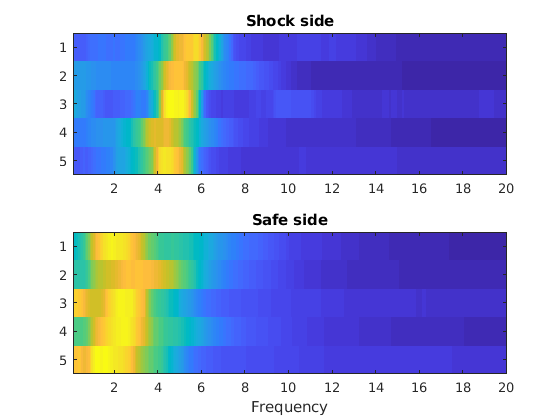

figure
for mm=1:5
    AllShock(mm,:)=mean(SpecData{mm}.Shock);
    AllSafe(mm,:)=mean(SpecData{mm}.Safe);
end
subplot(211)
imagesc(fLow,[1:5],zscore(AllShock')')
title('Shock side')
subplot(212)
imagesc(fLow,[1:5],zscore(AllSafe')')
title('Safe side')
xlabel('Frequency')

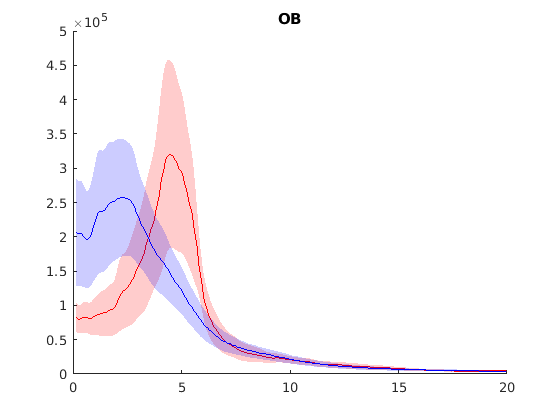


for mm=1:size(SpecData,1)
    denom = nanmean(nanmean(SpecData{mm}.Shock(:,15:end))) + nanmean(nanmean(SpecData{mm}.Safe(:,15:end)));
    AllShock(mm,:)=nanmean(SpecData{mm}.Shock)./denom;
    AllSafe(mm,:)=nanmean(SpecData{mm}.Safe)./denom;
    denom = nanmean(nanmean(SpecDataH{mm}.Shock(:,15:end))) + nanmean(nanmean(SpecDataH{mm}.Safe(:,15:end)));
    AllShockH(mm,:)=nanmean(SpecDataH{mm}.Shock)./denom;
    AllSafeH(mm,:)=nanmean(SpecDataH{mm}.Safe)./denom;
    denom = nanmean(nanmean(SpecDataHLo{mm}.Shock)) + nanmean(nanmean(SpecDataHLo{mm}.Safe));
    AllShockHLo(mm,:)=nanmean(SpecDataHLo{mm}.Shock)./denom;
    AllSafeHLo(mm,:)=nanmean(SpecDataHLo{mm}.Safe)./denom;
end
figure
[hl,hp]=boundedline(fLow,nanmean(AllShock),[stdError(AllShock);stdError(AllShock)]','r','alpha');hold on
[hl,hp]=boundedline(fLow,nanmean(AllSafe),[stdError(AllSafe);stdError(AllSafe)]','b','alpha');
title('OB')

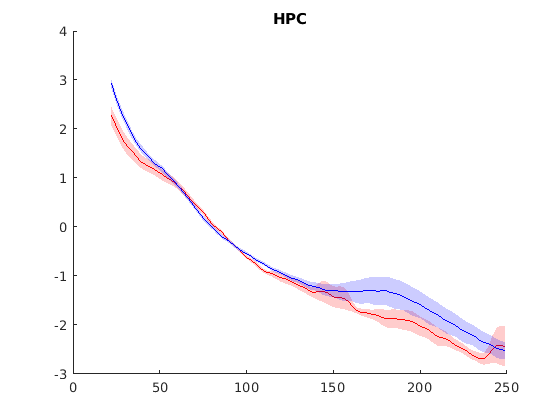

figure
[hl,hp]=boundedline(fHigh,nanmean(log(AllShockH)),[stdError(log(AllShockH));stdError(log(AllShockH))]','r','alpha');hold on
[hl,hp]=boundedline(fHigh,nanmean(log(AllSafeH)),[stdError(log(AllSafeH));stdError(log(AllSafeH))]','b','alpha');
title('HPC')

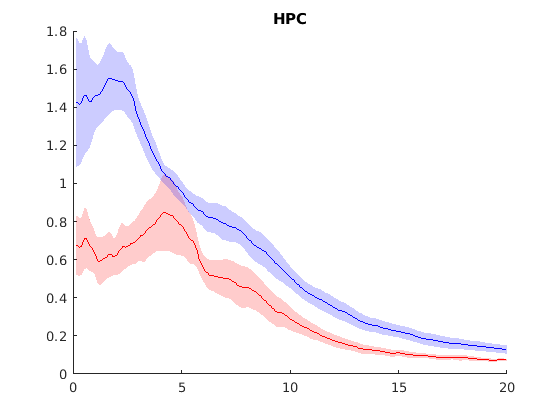

figure
[hl,hp]=boundedline(fLow,nanmean((AllShockHLo)),[stdError((AllShockHLo));stdError((AllShockHLo))]','r','alpha');hold on
[hl,hp]=boundedline(fLow,nanmean((AllSafeHLo)),[stdError((AllSafeHLo));stdError((AllSafeHLo))]','b','alpha');
title('HPC')

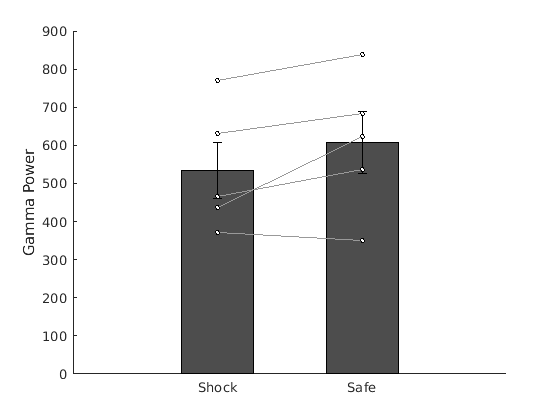

figure
PlotErrorBarN([nanmean(GammaOB.Shock');nanmean(GammaOB.Safe')]');
ylabel('Gamma Power')
set(gca,'XTick',[1,2],'XTickLabel',{'Shock','Safe'})

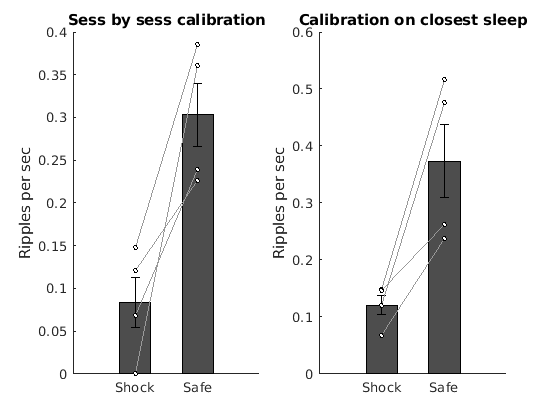

figure
subplot(121)
PlotErrorBarN([nanmean([NumRip.Shock.Sess./DurPer.Shock.Sess]');nanmean([NumRip.Safe.Sess./DurPer.Safe.Sess]')]',0,1);
set(gca,'XTick',[1,2],'XTickLabel',{'Shock','Safe'})
ylabel('Ripples per sec')
title('Sess by sess calibration')
subplot(122)
PlotErrorBarN([nanmean([NumRip.Shock.Sleep./DurPer.Shock.Sleep]');nanmean([NumRip.Safe.Sleep./DurPer.Safe.Sleep]')]',0,1);
ylabel('Ripples per sec')
set(gca,'XTick',[1,2],'XTickLabel',{'Shock','Safe'})
title('Calibration on closest sleep')

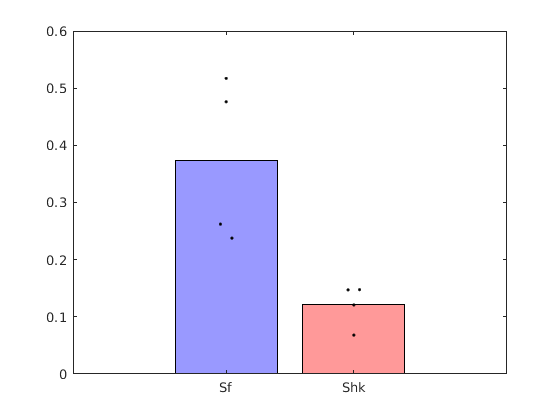


figure
bar(1,nanmean(nanmean([NumRip.Safe.Sleep./DurPer.Safe.Sleep]')),'FaceColor',[0.6 0.6 1]), hold on
bar(2,nanmean(nanmean([NumRip.Shock.Sleep./DurPer.Shock.Sleep]')),'FaceColor',[1 0.6 0.6])
plotSpread({nanmean([NumRip.Safe.Sleep./DurPer.Safe.Sleep]');nanmean([NumRip.Shock.Sleep./DurPer.Shock.Sleep]')},'distributionColors',[ 0 0 0;0 0 0])
set(gca,'XTick',[1,2],'XTickLabel',{'Sf','Shk'})

AllSafeHR=[];AllShockHR=[];AllMovHR=[];
AllSafeHRStd=[];AllShockHRStd=[];AllMovHRStd=[];

for mm=[3,5]
    for k=1:9
        AllShockHR=[AllShockHR,HRSliceBySlice.Shk{mm,k}.MeanHR];
        AllSafeHR=[AllSafeHR,HRSliceBySlice.Sf{mm,k}.MeanHR];
        AllSafeHRStd=[AllSafeHRStd,HRSliceBySlice.Sf{mm,k}.StdHR];
        AllShockHRStd=[AllShockHRStd,HRSliceBySlice.Shk{mm,k}.StdHR];
        AllMovHR=[AllMovHR,HRSliceBySlice.Mv{mm,k}.MeanHR];
        AllMovHRStd=[AllMovHRStd,HRSliceBySlice.Mv{mm,k}.StdHR];
    end
end

figure
subplot(211)
nhist({AllSafeHR,AllShockHR,AllMovHR});
legend('Safe','Shk','Mov')
title('Mean HR')
subplot(212)
nhist({AllSafeHRStd,AllShockHRStd,AllMovHRStd});
legend('Safe','Shk','Mov')
title('Std HR')


ShkSf={'Shock','Safe'};
for ss=1:2
    for mm=1:5
        SpectrogramFinal.(ShkSf{ss}){mm}=zeros(94,201);
        for sess=1:9
            if not(isnan(NumRip.(ShkSf{ss}).Sess(mm,sess))) & NumRip.(ShkSf{ss}).Sess(mm,sess)>0
                SpectrogramFinal.(ShkSf{ss}){mm}=SpectrogramFinal.Shock{mm}+Spectrogram.(ShkSf{ss}){mm,sess}*NumRip.(ShkSf{ss}).Sess(mm,sess);
            end
            SpectrogramFinal.(ShkSf{ss}){mm}=SpectrogramFinal.(ShkSf{ss}){mm}/nansum(NumRip.(ShkSf{ss}).Sess(mm,:));
        end
    end
    
end


clear all
SessionNames={'ExtinctionBlockedShock_EyeShock' 'ExtinctionBlockedSafe_EyeShock' };
ShkSf={'Shock','Safe'};
for mm=1:5
    for ss=1:length(SessionNames)
        SpecData.(ShkSf{ss}){mm}=[];
        SpecDataH.(ShkSf{ss}){mm}=[];
        SpecDataHLo.(ShkSf{ss}){mm}=[];
        Files=PathForExperimentsEmbReact(SessionNames{ss});
        MouseToAvoid=[560]; % mice with noisy data to exclude
        Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
        
        for c=1
            cd(Files.path{mm}{c})
            load('behavResources_SB.mat')
            dt=median(diff(Range(Behav.Vtsd,'s')));
            if not(isempty(Behav.FreezeAccEpoch))
                FreezeEpoch=Behav.FreezeAccEpoch;
            else
                FreezeEpoch=Behav.FreezeEpoch;
            end
            load('B_Low_Spectrum.mat')
            fLow=Spectro{3};
            Sptsd=tsd(Spectro{2}*1e4,Spectro{1});
            load('H_Low_Spectrum.mat')
            SptsdHLo=tsd(Spectro{2}*1e4,Spectro{1});
            clear TotalNoiseEpoch smooth_ghi
            load('StateEpochSB.mat','TotalNoiseEpoch','smooth_ghi')
            RemovEpoch=TotalNoiseEpoch;
            
            if exist('ChannelsToAnalyse/dHPC_rip.mat')>0
                load('H_VHigh_Spectrum.mat')
                SptsdH=tsd(Spectro{2}*1e4,Spectro{1});
                fHigh=Spectro{3};
                try
                    load('RipplesSleepThresh.mat')
                    RiptsdSL=ts(Rip(:,2)*1e4);
                    load('Ripples.mat')
                    Riptsd=ts(Rip(:,2)*1e4);
                catch
                    disp('ripple problem')
                    Riptsd=ts(0.1*1e4);
                    RiptsdSL=ts(0.1*1e4);
                end
            end
            
            
            LitEp=dropShortIntervals(Behav.FreezeEpoch-RemovEpoch,3*1e4);
            GammaOB.(ShkSf{ss})(mm,c)=nanmean(Data(Restrict(smooth_ghi,LitEp)));
            SpecData.(ShkSf{ss}){mm}=[SpecData.(ShkSf{ss}){mm};Data(Restrict(Sptsd,LitEp))];
            SpecDataHLo.(ShkSf{ss}){mm}=[SpecDataHLo.(ShkSf{ss}){mm};Data(Restrict(SptsdHLo,LitEp))];
            ttemp=nansum(Stop(LitEp,'s')-Start(LitEp,'s'));
            if isempty(ttemp)
                DurFzTime.(ShkSf{ss})(mm,c)=0;
            else
                DurFzTime.(ShkSf{ss})(mm,c)=nansum(Stop(LitEp,'s')-Start(LitEp,'s'));
            end
            if exist('ChannelsToAnalyse/dHPC_rip.mat')>0
                SpecDataH.(ShkSf{ss}){mm}=[SpecDataH.(ShkSf{ss}){mm};Data(Restrict(SptsdH,LitEp))];
                if not(isempty(Start(LitEp)))
                    NumRip.(ShkSf{ss}).Sess(mm,c)=length(Range(Restrict(Riptsd,LitEp)));
                    DurPer.(ShkSf{ss}).Sess(mm,c)=nansum(Stop(LitEp,'s')-Start(LitEp,'s'));
                    NumRip.(ShkSf{ss}).Sleep(mm,c)=length(Range(Restrict(RiptsdSL,LitEp)));
                    DurPer.(ShkSf{ss}).Sleep(mm,c)=nansum(Stop(LitEp,'s')-Start(LitEp,'s'));
                    
                else
                    NumRip.(ShkSf{ss}).Sess(mm,c)=NaN;
                    DurPer.(ShkSf{ss}).Sess(mm,c)=NaN;
                    NumRip.(ShkSf{ss}).Sleep(mm,c)=NaN;
                    DurPer.(ShkSf{ss}).Sleep(mm,c)=NaN;
                end
            else
                NumRip.(ShkSf{ss}).Sess(mm,c)=NaN;
                DurPer.(ShkSf{ss}).Sess(mm,c)=NaN;
                NumRip.(ShkSf{ss}).Sleep(mm,c)=NaN;
                DurPer.(ShkSf{ss}).Sleep(mm,c)=NaN;
            end
            
            if exist('ChannelsToAnalyse/EKG.mat')
                load('HeartBeatInfo.mat')
                [HRInfo.(ShkSf{ss}){mm,c+(ss-1)*3},HRSliceBySlice{ss}{mm,c+(ss-1)*3},SliceDur{ss}{mm,c+(ss-1)*3}]=CharacterizeHeartRateEpoch(EKG,LitEp,2);
            end
        end
        
    end
end

ripple problem
ripple problem
ripple problem
ripple problem
ripple problem
ripple problem
ripple problem
ripple problem


disp('OK')

OK


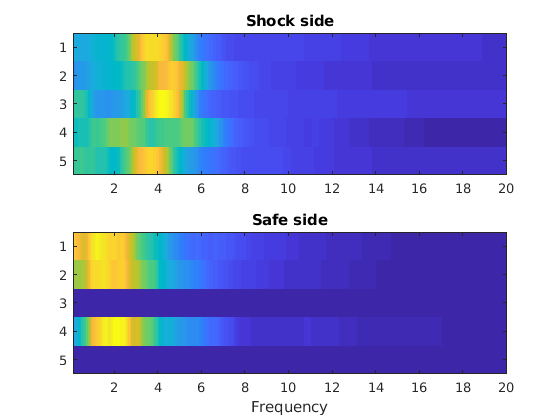

figure
for mm=1:5
    AllShock(mm,:)=mean(SpecData.Shock{mm});
    AllSafe(mm,:)=mean(SpecData.Safe{mm});
end
subplot(211)
imagesc(fLow,[1:5],zscore(AllShock')')
title('Shock side')
subplot(212)
imagesc(fLow,[1:5],zscore(AllSafe')')
title('Safe side')
xlabel('Frequency')

for mm=1:5
    AllShock(mm,:)=mean(SpecData.Shock{mm});
    AllSafe(mm,:)=mean(SpecData.Safe{mm});
    AllShockH(mm,:)=mean(SpecDataH.Shock{mm});
    AllSafeH(mm,:)=mean(SpecDataH.Safe{mm});
    AllShockHLo(mm,:)=mean(SpecDataHLo.Shock{mm});
    AllSafeHLo(mm,:)=mean(SpecDataHLo.Safe{mm});
end
figure
[hl,hp]=boundedline(fLow,nanmean(AllShock),[stdError(AllShock);stdError(AllShock)]','r','alpha'),hold on

hl =            1.0023193359375


hp =            0.0023193359375


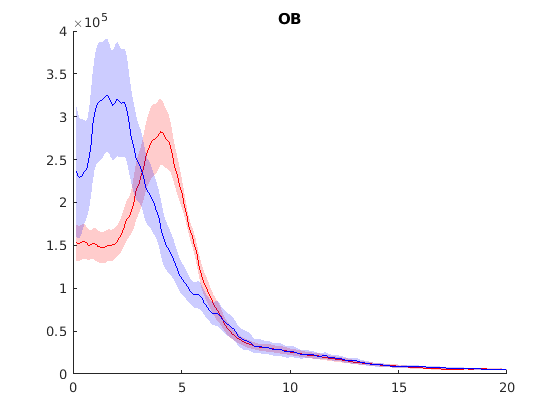

[hl,hp]=boundedline(fLow,nanmean(AllSafe),[stdError(AllSafe);stdError(AllSafe)]','b','alpha');
title('OB')

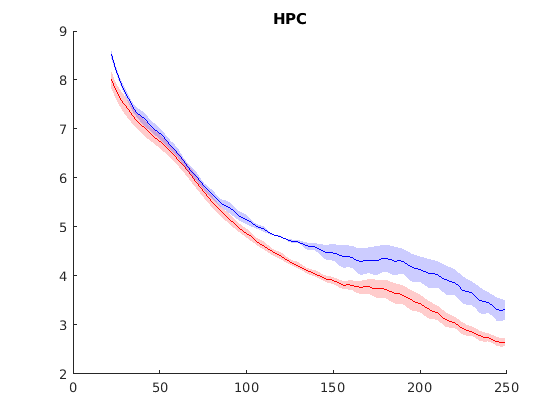

figure
[hl,hp]=boundedline(fHigh,nanmean(log(AllShockH)),[stdError(log(AllShockH));stdError(log(AllShockH))]','r','alpha');hold on
[hl,hp]=boundedline(fHigh,nanmean(log(AllSafeH)),[stdError(log(AllSafeH));stdError(log(AllSafeH))]','b','alpha');
title('HPC')

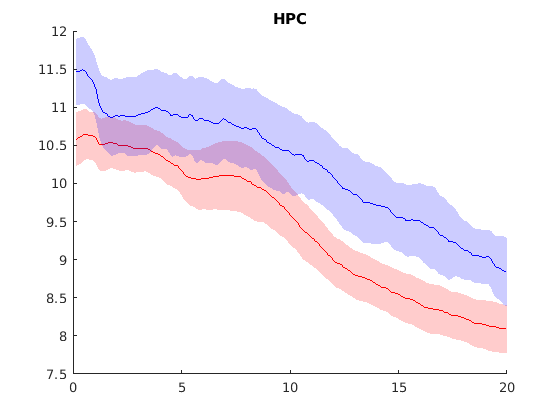

figure
[hl,hp]=boundedline(fLow,nanmean(log(AllShockHLo)),[stdError(log(AllShockHLo));stdError(log(AllShockHLo))]','r','alpha');hold on
[hl,hp]=boundedline(fLow,nanmean(log(AllSafeHLo)),[stdError(log(AllSafeHLo));stdError(log(AllSafeHLo))]','b','alpha');
title('HPC')

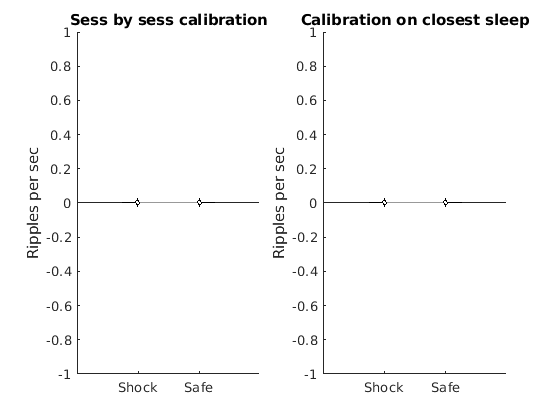

figure
subplot(121)
PlotErrorBarN([([NumRip.Shock.Sess./DurPer.Shock.Sess]');([NumRip.Safe.Sess./DurPer.Safe.Sess]')]',0,1);
set(gca,'XTick',[1,2],'XTickLabel',{'Shock','Safe'})
ylabel('Ripples per sec')
title('Sess by sess calibration')
subplot(122)
PlotErrorBarN([([NumRip.Shock.Sleep./DurPer.Shock.Sleep]');([NumRip.Safe.Sleep./DurPer.Safe.Sleep]')]',0,1);
ylabel('Ripples per sec')
set(gca,'XTick',[1,2],'XTickLabel',{'Shock','Safe'})
title('Calibration on closest sleep')

figure
PlotErrorBarN([(GammaOB.Shock');(GammaOB.Safe')]');
ylabel('Gamma Power')
set(gca,'XTick',[1,2],'XTickLabel',{'Shock','Safe'})

figure,
PlotErrorBarN([DurPer.Shock.Sess,DurPer.Safe.Sess],0);
